M-PSK

%Single Circle - 8PSK 
M = 8; 
nb = 10000;
EbNo = 10; 
packets = 10; 
window = 4; 
rng(0)
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 3, 'EbNo', EbNo); %create awgn channel object

msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

constDiagram(noisySig); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

x_train = zeros(size(train_data,1),size(train_data,2)*packets);
y_train = zeros(size(target,1),size(target,2)*packets);

%validation data
msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

val_data = makeInputMat(noisySig,window);
val_target = round([real(symbols) imag(symbols)],5)';

%train data
for iter = 1:packets
    x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
    y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
    if iter ~= packets
        msg = randi([0 M-1], nb, 1);
        symbols = pskmod(msg, M, pi/M);
        noisySig = awgnChan(symbols); 
        
        train_data = makeInputMat(noisySig,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
    end 
end 

x_train = x_train'; 
y_train = y_train';

val_data = val_data'; 
val_target = val_target'; 

path = pwd; 

filename_train = '8PSK_data';
save([path,'\',filename_train], 'x_train', 'y_train', 'val_data', 'val_target');

%prediction data
msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = '8PSK_pred'; 
save([path, '\',filename_test], 'train_data', 'target');

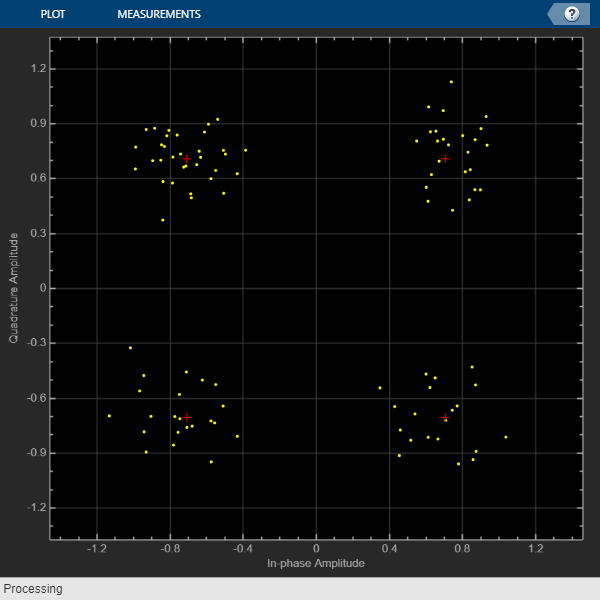

%QPSK 
M = 4; 
nb = 10000;
EbNo = 10; 
packets = 10; 
window = 4; 
rng(0)
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 2, 'EbNo', EbNo); %create awgn channel object

msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

constDiagram(noisySig); 


train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

x_train = zeros(size(train_data,1),size(train_data,2)*packets);
y_train = zeros(size(target,1),size(target,2)*packets);

%validation data
msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

val_data = makeInputMat(noisySig,window);
val_target = round([real(symbols) imag(symbols)],5)';

%train data
for iter = 1:packets
    x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
    y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
    if iter ~= packets
        msg = randi([0 M-1], nb, 1);
        symbols = pskmod(msg, M, pi/M);
        noisySig = awgnChan(symbols); 
        
        train_data = makeInputMat(noisySig,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
    end 
end 

x_train = x_train'; 
y_train = y_train';

val_data = val_data'; 
val_target = val_target'; 

path = pwd; 

filename_train = 'QPSK_data';
save([path,'\', filename_train], 'x_train', 'y_train', 'val_data', 'val_target');

%prediction data
msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = 'QPSK_pred'; 
save([path, '\',filename_test], 'train_data', 'target');

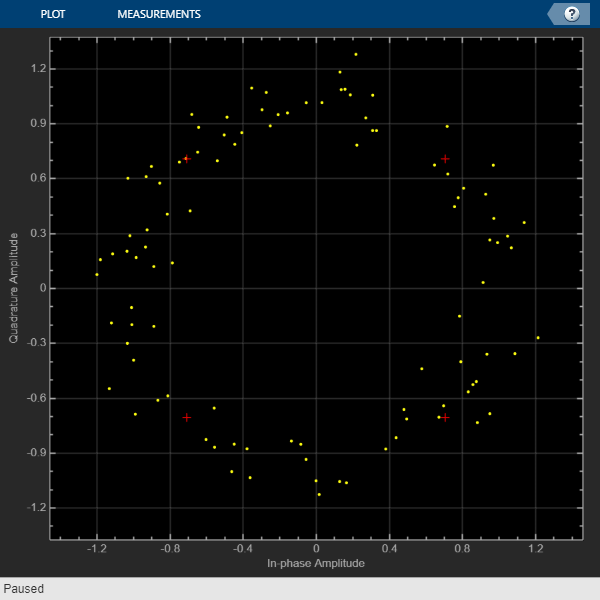

%16-PSK
%QPSK 
M = 16; 
nb = 10000;
EbNo = 10; 
packets = 10; 
window = 4; 
rng(0)
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', EbNo); %create awgn channel object

msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

constDiagram(noisySig); 


train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

x_train = zeros(size(train_data,1),size(train_data,2)*packets);
y_train = zeros(size(target,1),size(target,2)*packets);

%validation data
msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

val_data = makeInputMat(noisySig,window);
val_target = round([real(symbols) imag(symbols)],5)';

%train data
for iter = 1:packets
    x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
    y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
    if iter ~= packets
        msg = randi([0 M-1], nb, 1);
        symbols = pskmod(msg, M, pi/M);
        noisySig = awgnChan(symbols); 
        
        train_data = makeInputMat(noisySig,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
    end 
end 

x_train = x_train'; 
y_train = y_train';

val_data = val_data'; 
val_target = val_target'; 

path = pwd; 

filename_train = '16PSK_data';
save([path,'\', filename_train], 'x_train', 'y_train', 'val_data', 'val_target');

%prediction data
msg = randi([0 M-1], nb, 1);
symbols = pskmod(msg, M, pi/M);
noisySig = awgnChan(symbols); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = '16PSK_pred'; 
save([path, '\',filename_test], 'train_data', 'target');

16-APSK

M = [4 12];
nb = 10000; 
radii = [0.3 1];

EbNo = 10; 
packets = 10; 
window = 4; 
rng(0)

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', EbNo); %create awgn channel object

msg = randi([0 sum(M)-1], nb, 1);
symbols = apskmod(msg, M, radii); 
noisySig = awgnChan(symbols); 

%constDiagram(symbols); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

x_train = zeros(size(train_data,1),size(train_data,2)*packets);
y_train = zeros(size(target,1),size(target,2)*packets);

%validation data
msg = randi([0 sum(M)-1], nb, 1);
symbols = apskmod(msg, M, radii);
noisySig = awgnChan(symbols); 

val_data = makeInputMat(noisySig,window);
val_target = round([real(symbols) imag(symbols)],5)';

%train data
for iter = 1:packets
    x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
    y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
    if iter ~= packets
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = apskmod(msg, M, radii);
        noisySig = awgnChan(symbols);
        
        train_data = makeInputMat(noisySig,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
    end 
end 

x_train = x_train'; 
y_train = y_train';

val_data = val_data'; 
val_target = val_target'; 

path = pwd; 

filename_train = '16APSK_data';
save([path,'\', filename_train], 'x_train', 'y_train', 'val_data', 'val_target');

%prediction data
msg = randi([0 sum(M)-1], nb, 1);
symbols = apskmod(msg, M, radii);
noisySig = awgnChan(symbols);

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = '16APSK_pred'; 
save([path, '\',filename_test], 'train_data', 'target'); 

%8-APSK - weird mod order
M = [4 4];
nb = 10000; 
radii = [0.3 1];

EbNo = 10; 
packets = 10; 
window = 4; 
rng(0)

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 3, 'EbNo', EbNo); %create awgn channel object

msg = randi([0 sum(M)-1], nb, 1);
symbols = apskmod(msg, M, radii); 
noisySig = awgnChan(symbols); 

%constDiagram(symbols); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

x_train = zeros(size(train_data,1),size(train_data,2)*packets);
y_train = zeros(size(target,1),size(target,2)*packets);

%validation data
msg = randi([0 sum(M)-1], nb, 1);
symbols = apskmod(msg, M, radii);
noisySig = awgnChan(symbols); 

val_data = makeInputMat(noisySig,window);
val_target = round([real(symbols) imag(symbols)],5)';

%train data
for iter = 1:packets
    x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
    y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
    if iter ~= packets
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = apskmod(msg, M, radii);
        noisySig = awgnChan(symbols);
        
        train_data = makeInputMat(noisySig,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
    end 
end 

x_train = x_train'; 
y_train = y_train';

val_data = val_data'; 
val_target = val_target'; 

path = pwd; 

filename_train = '8APSK_data';
save([path,'\', filename_train], 'x_train', 'y_train', 'val_data', 'val_target');

%prediction data
msg = randi([0 sum(M)-1], nb, 1);
symbols = apskmod(msg, M, radii);
noisySig = awgnChan(symbols);

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = '8APSK_pred'; 
save([path, '\',filename_test], 'train_data', 'target'); 

%DVBS-APSK
M = 16

M = 16

nb = 10000; 

EbNo = 100; 
packets = 11; 
window = 4; 
rng(0)

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', EbNo); %create awgn channel object

msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x'); 
noisySig = awgnChan(symbols); 

%constDiagram(symbols); 

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

x_train = zeros(size(train_data,1),size(train_data,2)*packets);
y_train = zeros(size(target,1),size(target,2)*packets);

%validation data
msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x');
noisySig = awgnChan(symbols); 

val_data = makeInputMat(noisySig,window);
val_target = round([real(symbols) imag(symbols)],5)';

%train data
for iter = 1:packets
    x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
    y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
    if iter ~= packets
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = dvbsapskmod(msg, M, 's2x');
        noisySig = awgnChan(symbols);
        
        train_data = makeInputMat(noisySig,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
    end 
end 

x_train = x_train'; 
y_train = y_train';

val_data = val_data'; 
val_target = val_target'; 

path = pwd; 

filename_train = 'DVBSAPSK_data_test';
save([path,'\', filename_train], 'x_train', 'y_train', 'val_data', 'val_target');

%prediction data
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', 23); %create awgn channel object
nb = 5000; 
M=16;
window = 4;
msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x');
noisySig = awgnChan(symbols);

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = 'DVBSAPSK_pred_23_5e3'; 
save(filename_test, 'train_data', 'target'); 

%prediction data
rng(67)
awgnChan = comm.AWGNChannel('BitsPerSymbol', 4, 'EbNo', 10); %create awgn channel object
nb = 10000; 
M=16;
window = 4;
msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x');
noisySig = awgnChan(symbols);

train_data = makeInputMat(noisySig,window);
train_data = train_data(:,1:end-window);
symbols = symbols(1+window:end);
target = round([real(symbols) imag(symbols)],5)';

train_data = train_data'; 
filename_test = 'DVBSAPSK_pred_10_rngTest'; 
save(filename_test, 'train_data', 'target'); 